clear
close all
clc
seed = 1234

seed = 1234

rng(seed)

FNT_SZ = 16;

%% Set the LPA parameters

% maximum degree of polynomial used for fitting
N = 1;

% parameter for the confidence intervals in the ICI rule
Gamma = 2;

% Set all the scale values
hmax = 21;
all_h = 1:hmax;

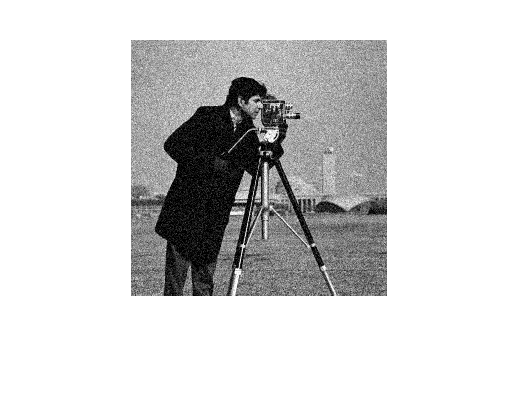

%% generate the image

% load the cameraman image
y = im2double(imread('cameraman.tif'));

% noise standard deviation
sigma = 20/255;

% noisy signal 
s = y + sigma*randn(size(y));

figure()
imshow(s)

%% generate the LPA kernels for all the scale
all_g = cell(length(all_h),1);
for ii=1:length(all_h)
    h = all_h(ii);
    
    % define the symmetric weights for the scale h

    %"block weights"
    %w = zeros(2*h-1, 2*h-1);
    %w((1:round(end/2)),(1:round(end/2))) = 1;
    

    
    %All ones 
    w = ones(2*h -1, 2*h -1);
    w = w/norm(w, 2);
    
    
    % compute and store the kernel g
    g = compute_LPA_kernel(w, N);
    
    % store the kernel
    all_g{ii} = g;
    
end


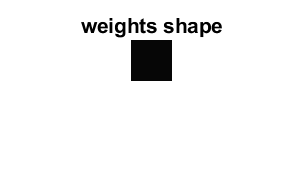

figure, imshow(w, []);
title("weights shape")


%% find the best scale for each sample using the LPA-ICI rule
% initialize the lower and upper bound vectors
lower_bounds = -ones(size(s))*Inf;
upper_bounds = ones(size(s))*Inf;

% initialize the final estimate and the best scale image
sfinal = zeros(size(s));
best_scale = zeros(size(s));

% loop over all the scales
for ii=1:length(all_h)
    
    h = all_h(ii);
    g = all_g{ii};
    
    % compute the estimate for the scale h
    shat = conv2(s, g, "same");
        
    % compute the lower and upper bound of the confidence interval for this
    % scale
    lb = shat - Gamma*sigma*norm(g, 2);
    ub = shat + Gamma*sigma*norm(g, 2);

    % update the lower and upper bounds 
    lower_bounds = max(lower_bounds, lb);
    upper_bounds = min(upper_bounds, ub);
    
    % update the best scale and the final estimate
    
    %upgrade sfinal until upper_bounds<lower_bounds
    idx = find(upper_bounds > lower_bounds);
    sfinal(idx) = shat(idx);
    %if upper_bounds>lower_bounds save best_scale
    idx = find((upper_bounds < lower_bounds) .* (best_scale==0));
    if ~isempty(idx)
        best_scale(idx) = h-1;
    end
end

idx = find(best_scale==0);
if ~isempty(idx)
   best_scale(idx) = h;
end
%%


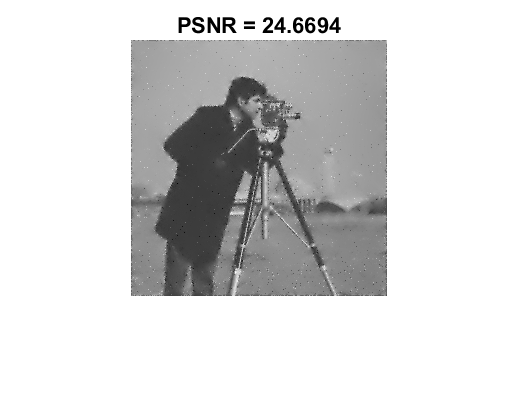

% compute the psnr
psnr_sfinal = 10 * log10(1/mean((y-sfinal).^2, "all"));

close 
figure, imshow(sfinal, []);
title(['PSNR = ', num2str(psnr_sfinal)])

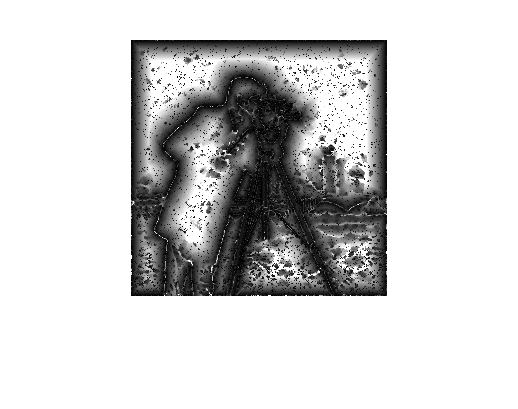

figure, imshow(best_scale, []);